Aerofoil

## **Aerofoil shape**

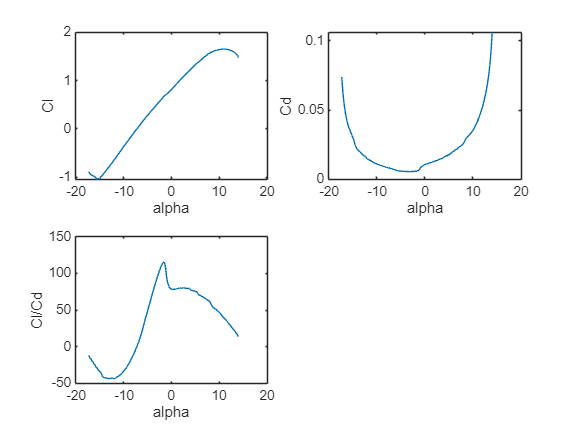

airfoil = Airfoil();
airfoil = airfoil.readPolar("xf-sc21010-il-1000000.csv");
airfoil = airfoil.readShape("sc21010.dat.txt");
airfoil = airfoil.interpShape(9);
figure(1)
clf;
airfoil.plotPolar()

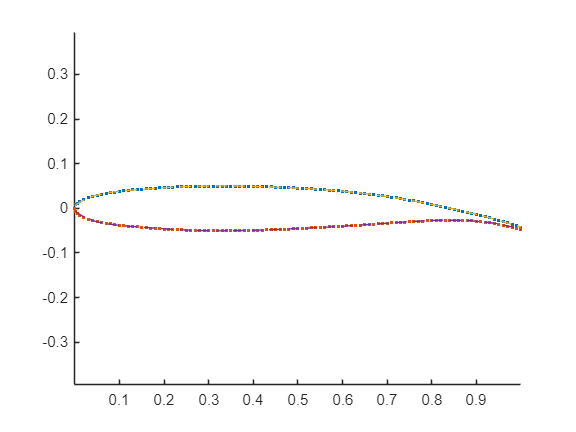


figure(2)
clf;
airfoil.plotShape()


airfoil

airfoil =   Airfoil with properties:

            alpha: [125×1 double]
               Cl: [125×1 double]
               Cd: [125×1 double]
       uppershape: [103×2 double]
       lowershape: [103×2 double]
    upperShapefun: @(x_c)polyval(p_upper,x_c)
    lowerShapefun: @(x_c)polyval(p_lower,x_c)
              x_c: [0 0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0261 0.0281 0.0301 0.0321 0.0341 0.0361 0.0381 0.0401 0.0421 0.0441 0.0461 0.0481 0.0501 0.0521 0.0541 0.0561 0.0581 0.0601 … ] (1×500 double)
           t_cfun: @(x_c)polyval(p_thickness,x_c)
              t_c: 0.1007
             x_cm: 0.3246


Wing Definition:

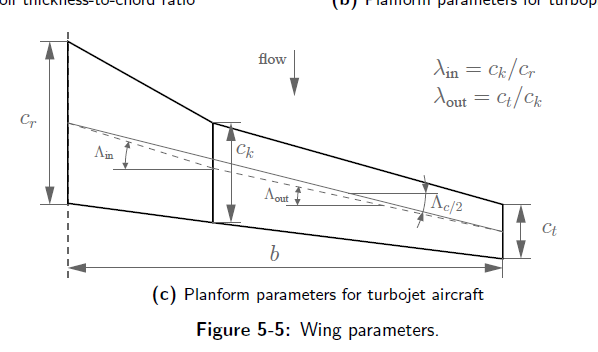

Define wing:

wing = WingGeometry();
wing.cr = 4.9;
wing.ck = 3.5;
wing.ct = 1.5;
wing.s = 28.45/2;
wing.Lambdain50 = 0*pi/180;
wing.Lambdaout50 = 0*pi/180;
wing.yk = 5.69;
wing = wing.calcSref()

wing =   WingGeometry with properties:

             cr: 4.9000
             ck: 3.5000
             ct: 1.5000
              s: 14.2250
             yk: 5.6900
     Lambdain50: 0
    Lambdaout50: 0
              N: []
             Sc: []
         stripy: []
             AR: 8.9465
            Sin: 47.7960
           Sout: 42.6750
           cbar: 3.3500
              b: 28.4500
           SREF: 90.4710


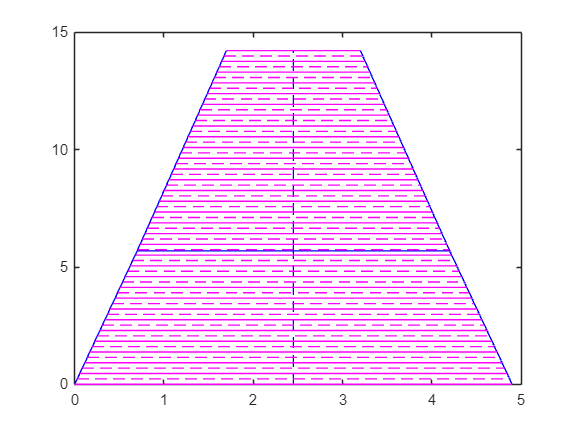

wing.N = 31;
figure(3)
clf;
axis equal
wing.plotWing()
wing.c_at_y(10);
wing = wing.createStrips();
wing.plotStrips();

wing = wing.calcSc()

wing =   WingGeometry with properties:

             cr: 4.9000
             ck: 3.5000
             ct: 1.5000
              s: 14.2250
             yk: 5.6900
     Lambdain50: 0
    Lambdaout50: 0
              N: 31
             Sc: [2.2226 2.1708 2.1189 2.0671 2.0153 1.9635 1.9117 1.8599 1.8081 1.7563 1.7045 1.6527 1.6016 1.5518 1.5024 1.4531 1.4038 1.3544 1.3051 1.2557 1.2064 1.1570 1.1077 1.0584 1.0090 0.9597 0.9103 0.8610 0.8117 0.7623 0.7130]
         stripy: [0.2294 0.6883 1.1472 1.6060 2.0649 2.5238 2.9827 3.4415 3.9004 4.3593 4.8181 5.2770 5.7359 6.1948 6.6536 7.1125 7.5714 8.0302 8.4891 8.9480 9.4069 9.8657 10.3246 10.7835 11.2423 11.7012 12.1601 12.6190 13.0778 13.5367 13.9956]
             AR: 8.9465
            Sin: 47.7960
           Sout: 42.6750
           cbar: 3.3500
              b: 28.4500
           SREF: 90.4710


Cruise Condition

%Chord length
c = wing.cbar;
cruise = AirCondition()

cruise =   AirCondition with properties:

      M: []
      V: []
      h: []
    rho: []
      T: []
      a: []
      P: []
     nu: []
     mu: []
     Re: []


cruise.M = 0.8;
cruise.h = convlength(39000, 'ft','m');
cruise = cruise.init(wing.cbar)

cruise =   AirCondition with properties:

      M: 0.8000
      V: 236.0557
      h: 1.1887e+04
    rho: 0.3164
      T: 216.6500
      a: 295.0696
      P: 1.9677e+04
     nu: 4.4930e-05
     mu: 1.4216e-05
     Re: 1.7600e+07


## Lifting Line Theory

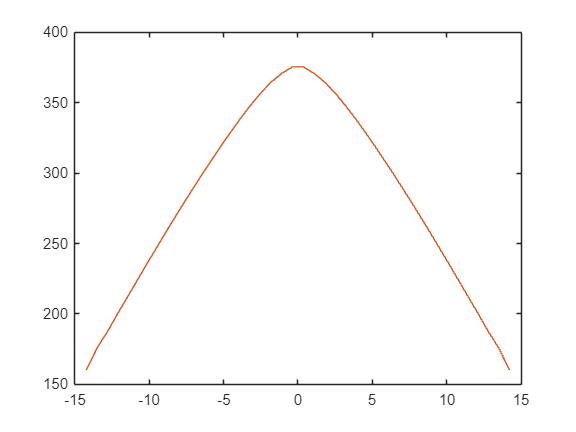

Process is complete! Converged circulation distribution found.


CLclean = 0.7532

CDi = 0.0085

Cly =   -14.2250  -13.4955  -12.7660  -12.0365  -11.3071  -10.5776   -9.8481   -9.1186   -8.3891   -7.6596   -6.9301   -6.2006   -5.4712   -4.7417   -4.0122   -3.2827   -2.5532   -1.8237   -1.0942   -0.3647    0.3647    1.0942    1.8237    2.5532    3.2827    4.0122    4.7417    5.4712    6.2006    6.9301    7.6596    8.3891    9.1186    9.8481   10.5776   11.3071   12.0365   12.7660   13.4955   14.2250
    0.0150    0.0165    0.0176    0.0189    0.0201    0.0213    0.0226    0.0238    0.0250    0.0261    0.0273    0.0284    0.0295    0.0305    0.0315    0.0325    0.0334    0.0341    0.0347    0.0352    0.0352    0.0347    0.0341    0.0334    0.0325    0.0315    0.0305    0.0295    0.0284    0.0273    0.0261    0.0250    0.0238    0.0226    0.0213    0.0201    0.0189    0.0176    0.0165    0.0150


[CLclean, CDi, Cly] = LLE_new(wing,airfoil,cruise,0,40,1e-2)

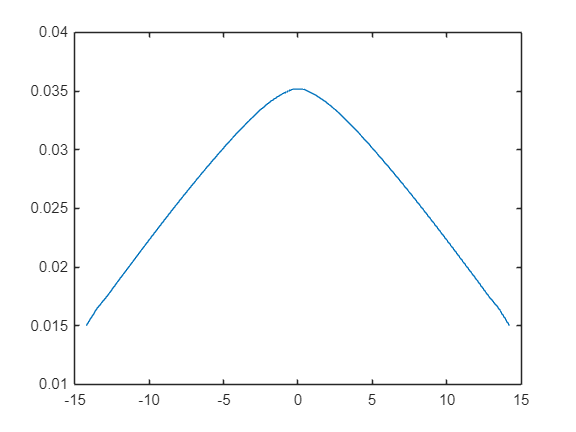

Swet_SrefWing = 2.2;
Swet_SrefBody = 5;
l_d = 10;
figure(2)
clf;
plot(Cly(1,:),Cly(2,:))

## Drag Model, Ref15

## Friction Drag

CDF = CDFfun(cruise.M, cruise.Re, wing, airfoil.x_cm, airfoil.t_c, l_d, Swet_SrefWing, Swet_SrefBody)

CDF = 0.0169

## Wave Drag

Integration of drag produced by each strip gives the total wave drag coefficient

CDW = CDWfun(wing,Cly,cruise.M,airfoil.t_c)

CDW = 2.5925e-04

Total Drag

CDtotal = CDF + CDW + CDi

CDtotal = 0.0256

L_D = CLclean/CDtotal

L_D = 29.4092

## Wing Weight

W_crew = 500 * 82.8;                     % Passenger weight + carry-on luggage (kg) % Ref 04 p.45
W_crew = W_crew + (12 + 4) * 79.4;       % Crew weight + carry-on luggage (kg)      % Roskam Part I p.8
W_payload = 500 * 17;                    % Passener checked luggage (kg)            % Ref 04 p.45
W_payload = W_payload + (12 + 4) * 13.6; % Crew checked luggage (kg)                % Roskam Part I p.8
Wpay = 9.81*(W_crew + W_payload)

Wpay = 5.0412e+05

Wto = 4.3895*1e5*9.81

Wto = 4.3061e+06

nult = 3.75; %Chatgpt, b777
range = convlength(7500, 'naut mi','m');

Ww = wingWeightLTH(wing,airfoil.t_c,Wto)

Ww = 3.3437e+05

%Ww = wingWeightHowe(wing,Wpay,Wto,nult,t_c,V,range*1e03)
mw = Ww/9.81 %one wing

mw = 3.4085e+04

## Performance

h_cruise2 = convlength(18000, 'ft','m');
[T_65, c_65, P_65, rho_65] = atmosisa(h_cruise2);
M_cruise2 =  convvel(400, 'kts', 'm/s')/c_65;
C_cruise = 0.5 ./ 3600;
[W_f_0, W_i] = Wf_W0(cruise.h, h_cruise2, cruise.M, M_cruise2, L_D, C_cruise)

W_f_0 = 0.3285

W_i =     0.9700    0.9850    0.7480    0.9900    0.9931    0.9826    0.9899    0.9954    0.9920



OPTindex = W_f_0*Ww %index to minimize

OPTindex = 1.0983e+05